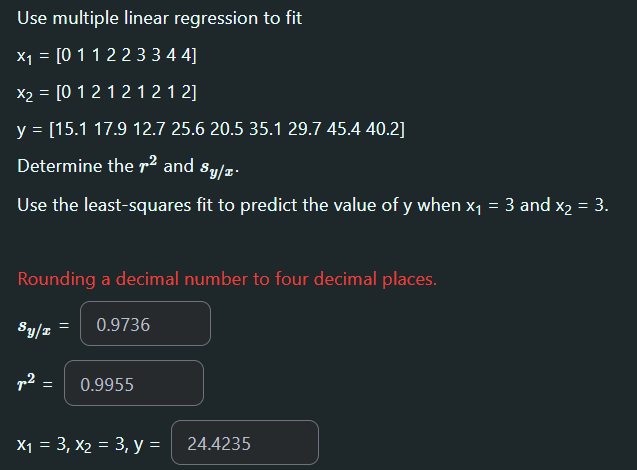

Data

x1 = [0 1 1 2 2 3 3 4 4]';
x2 = [0 1 2 1 2 1 2 1 2]';
y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2]';

z = [ones(size(x1)) x1 x2]

z =      1     0     0
     1     1     1
     1     1     2
     1     2     1
     1     2     2
     1     3     1
     1     3     2
     1     4     1
     1     4     2


%a0*1 + a1*x1 + a2*x2
a = (z'*z) \ (z'*y);

Sr = sum((y-z*a).^2)

Sr = 4.7397

St = sum((y-mean(y)).^2)

St = 1.0587e+03

r2 = round(1 - Sr/St,4)

r2 = 0.9955

syx = sqrt(Sr/(length(x1)-length(a)));
syx = round(syx,4)

syx = 0.8888


xtest1 = 3; xtest2 = 3;

y_pred = a(1) + a(2).*xtest1 + a(3).*xtest2;
y_pred = round(y_pred,4)

y_pred = 24.4235